#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

ODE          = Winx(true );
DT = 0.001;
T  = 180;

#### Initialize the solver class

solver = Heun();
solver.setODE( ODE );

#### Advance the ODE

s = 0;
theta1 =0;
theta2 =  0.3912390397;   %theta2 =2.750353614;
theta4 = 0.006780333643;   %theta4 = 3.134812320;
theta5 = 0;
theta6 = 0;
s__dot =0;
theta1__dot = 0;
theta2__dot = 0;
theta4__dot =0;
theta5__dot = 0;
theta6__dot = 0;
Zini = [ s, theta1,theta2,theta4,theta5,theta6 , s__dot, theta1__dot,theta2__dot,theta4__dot,theta5__dot,theta6__dot];

tt = 0:DT:T;
Z = solver.advance( tt, Zini);

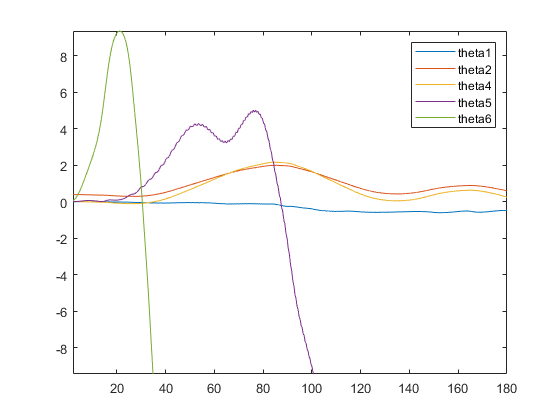

figure();
plot(tt,Z(2,:),tt,Z(3,:),tt,Z(4,:),tt,Z(5,:),tt,Z(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

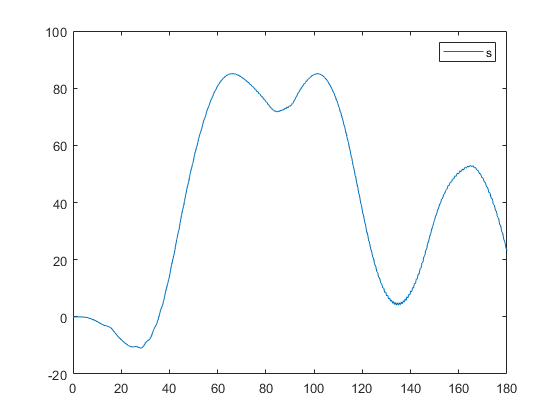

plot(tt,Z(1,:)); 
legend('s'); % s in another chart because the scale it's too different

#### Initialize the solver class

solver_P = Heun_P();
solver_P.setODE( ODE );

#### Advance the ODE

s = 0;
theta1 =0;
theta2 =  0.3912390397;   %theta2 =2.750353614;
theta4 = 0.006780333643;   %theta4 = 3.134812320;
theta5 = 0;
theta6 = 0;
s__dot =0;
theta1__dot = 0;
theta2__dot = 0;
theta4__dot =0;
theta5__dot = 0;
theta6__dot = 0;
Zini = [ s, theta1,theta2,theta4,theta5,theta6 , s__dot, theta1__dot,theta2__dot,theta4__dot,theta5__dot,theta6__dot];

tt = 0:DT:T;
Z0 = solver_P.advance( tt, Zini);

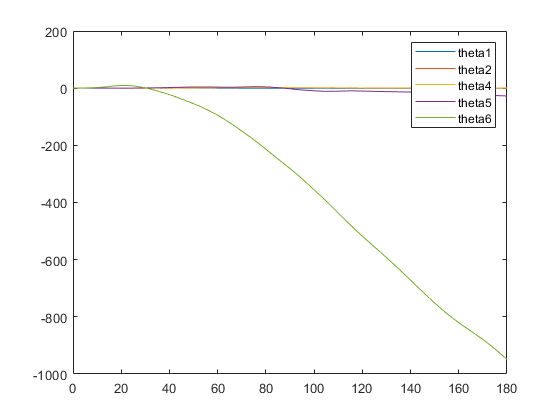

figure();
plot(tt,Z(2,:),tt,Z(3,:),tt,Z(4,:),tt,Z(5,:),tt,Z(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

plot(tt,Z(1,:)); 
legend('s');